Se importa el mapa binario de ocupación

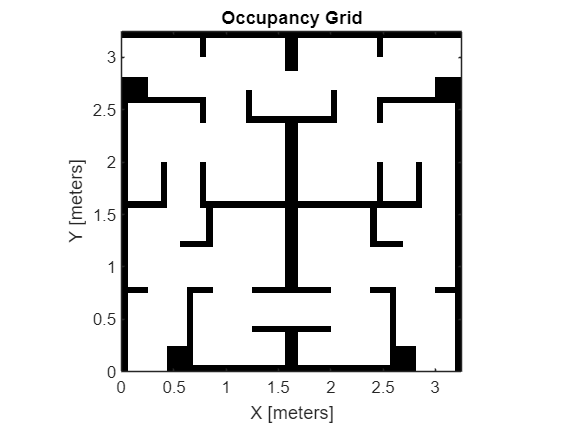

load("Celdas_binarias_ejercicio.mat");
map1 = occupancyMap(sm4b,16);   % Resolución de 16 celdas / metro
show(map1)

## Calculo del factor de inflado

El mapa que se nos da tiene una resolución de 16 celdas por metro. Como se vio en el mapa 1, eso equivale a un mapa de aproximadamente 3.2 x 3.2 metros. 

Para calcular el factor de inflado, se tendrán en cuenta los posibles caminos que puede tomar el robot. En la siguiente figura se puede ver la magnitud en pixeles de algunos.

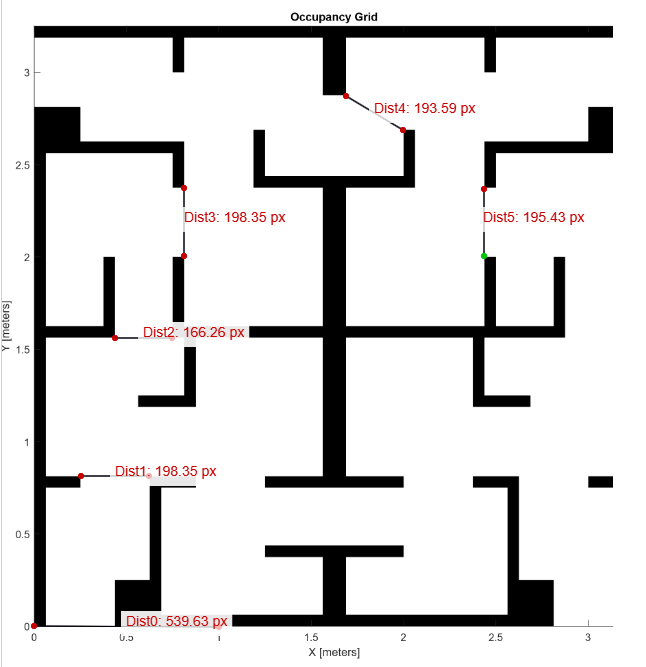

Para calcular el valor en metros, se usa una equivalencia de 539.63 pixeles por metro. 

metro = 539.63; % px / m
dist1 = 198.35/metro    % metros

dist1 = 0.3676

dist2 = 166.26/metro

dist2 = 0.3081

dist3 = 195.43/metro

dist3 = 0.3622

Con esto se puede ver que el camino más angosto que podría tener el robot es de 30.81 cm aproximadamente. Ya que el robot tiene un ancho de 15.8 cm, se encontrará el factor con la relación entre estas dos medidas.

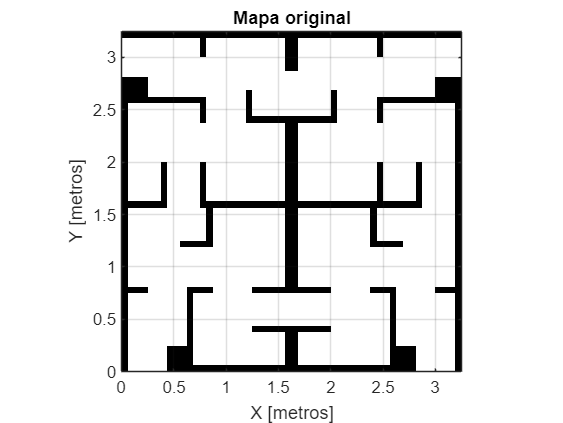

inflateMap = copy(map1);
inflate(inflateMap,0.06);
figure(1);
show(map1); title('Mapa original'); xlabel("X [metros]"); ylabel("Y [metros]")
grid on

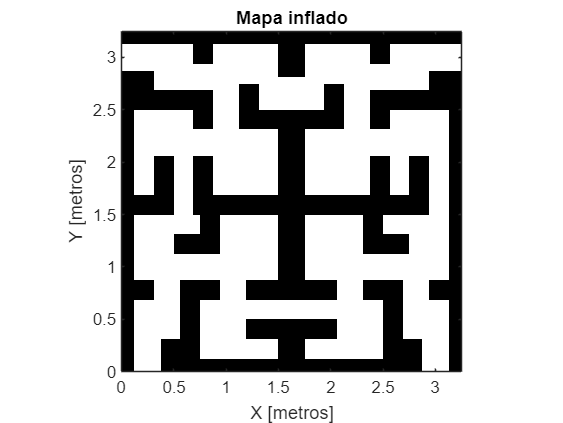


figure(2)
show(inflateMap); title('Mapa inflado'); xlabel("X [metros]"); ylabel("Y [metros]")

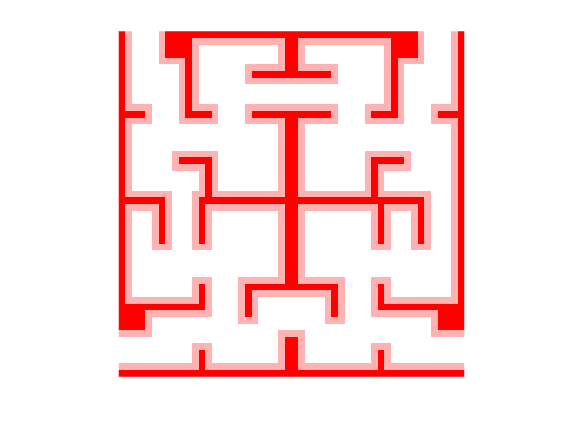

matOriginal = occupancyMatrix(map1);
matInflada = occupancyMatrix(inflateMap);


figure;
% 1. Primer eje: mapa inflado (fondo rojo claro)
ax1 = axes;
imagesc(flipud(matInflada), 'Parent', ax1);
colormap(ax1, [1 0.7 0.7; 1 0.7 0.7]);  % rojo claro
ax1.Visible = 'off';
axis equal tight;

% 2. Segundo eje: mapa original (rojo oscuro encima)
ax2 = axes;
imagesc(flipud(matOriginal), 'Parent', ax2);
colormap(ax2, [1 0 0; 1 0 0]);  % rojo fuerte
ax2.Visible = 'off';
axis equal tight;

% 3. Sincronizar posiciones de ambos ejes
linkaxes([ax1 ax2]);

% 4. Aplicar transparencia (solo mostrar donde hay obstáculos)
alphaDataOriginal = double(flipud(matOriginal > 0.5)); % 1 donde hay obstáculos, 0 donde no
alphaDataInflado = double(flipud(matInflada > 0.5));   % lo mismo para el inflado

% Asignar las transparencias
ax2.Children(1).AlphaData = alphaDataOriginal;
ax1.Children(1).AlphaData = alphaDataInflado;

## Dimensiones DR12

X: 0.23 m    Y: 0.158 m    Z: 0.1406 m

Radio de rueda = 0.086 m    Espesor de rueda = 0.026 m

Distancia entre ruedas = 0.154 m

## Modelo cinemático del robot


$$v = \frac{r}{2} \dot{\theta_1} + \frac{r}{2} \dot{\theta_2}$$



$$w = \frac{r}{2l} \dot{\theta_1} - \frac{r}{2l} \dot{\theta_2} $$


radio_rueda = 0.086;
espesor_rueda = 0.026;
dist_ruedas = 0.23;
initialState = [0; 0; 0];       % [x y theta]
tspan = [0 10];
inputs = [50 40];% vel rueda izquierda / derecha

% Ecuaciones de cinemática
v = (inputs(1) + inputs(2)) * radio_rueda / 2;
w = (inputs(1) - inputs(2)) * radio_rueda / (2 * dist_ruedas);
dx = v * cos(initialState(3));
dy = v * sin(initialState(3));
dtheta = w;
d_arr = [dx; dy; dtheta];
dyn = @(t,state) d_arr;

[t,states] = ode45(dyn, tspan, initialState);

robot = differentialDriveKinematics(WheelRadius=radio_rueda, ...
    TrackWidth=dist_ruedas, VehicleInputs='WheelSpeeds')

robot =   differentialDriveKinematics with properties:

      VehicleInputs: 'WheelSpeeds'
         TrackWidth: 0.2300
        WheelRadius: 0.0860
    WheelSpeedRange: [-Inf Inf]


## Probabilistic Roadmap Path planning

prm = mobileRobotPRM(inflateMap);
prm.NumNodes = 10000;
prm.ConnectionDistance = 0.05;
startLocation = [3.2 3];
endLocation = [0.2 0];
path = findpath(prm, startLocation, endLocation);

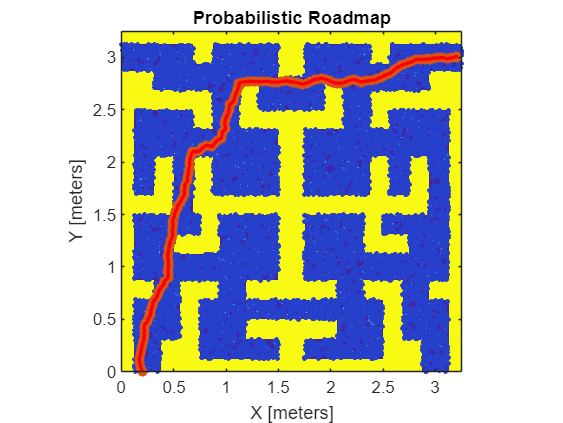

figure();
show(prm);
hold on
plot(path(:,1), path(:,2), 'r-', 'LineWidth', 2)

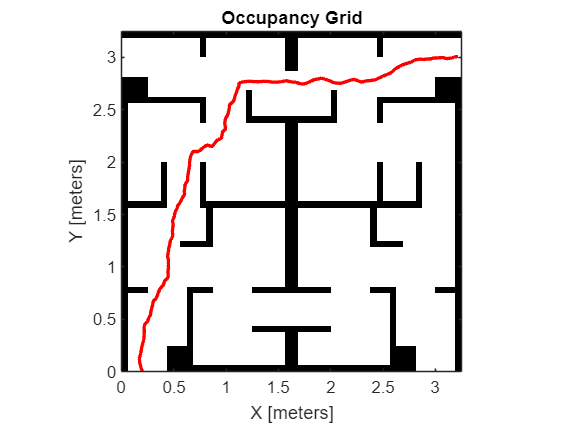


figure();
show(map1);
hold on
plot(path(:,1), path(:,2), 'r-', 'LineWidth', 2)

## Función de coste

costeTotal = sum(vecnorm(diff(path), 2, 2)) % en metros

costeTotal = 5.3248

## Rapidly-exploring Random Tree

stateSpace = stateSpaceSE2;
stateSpace.StateBounds = [inflateMap.XWorldLimits; inflateMap.YWorldLimits; [-pi,pi]];

validator = validatorOccupancyMap(stateSpace);
validator.Map = inflateMap;
validator.ValidationDistance = 0.1;

planner = plannerRRT(stateSpace, validator);
planner.MaxConnectionDistance = 2.0;
planner.MaxIterations  = 3000;

[pthObj, solnInfo] = plan(planner, [startLocation 0], [endLocation 0]);

states = pthObj.States;

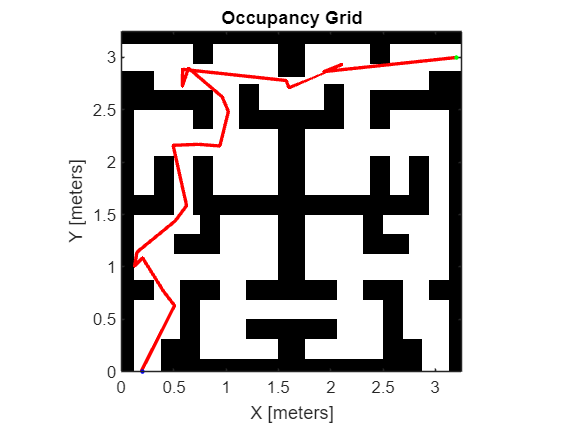

show(inflateMap);
hold on;
plot(states(:,1), states(:,2), 'r-', 'LineWidth', 2);
plot(startLocation(1), startLocation(2), 'g.', 'MarkerSize', 8, 'LineWidth', 2);
plot(endLocation(1), endLocation(2), 'b.', 'MarkerSize', 8, 'LineWidth', 2 );

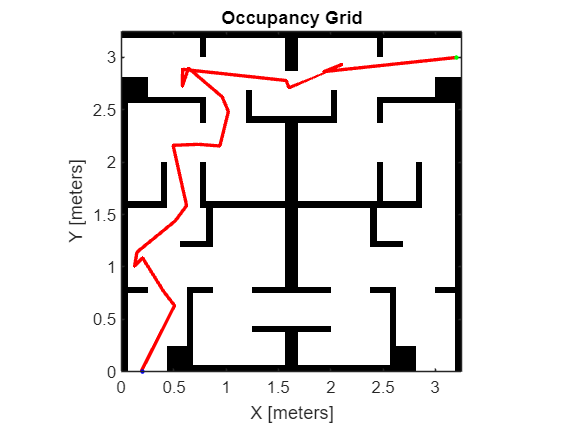


figure();
show(map1);
hold on
plot(states(:,1), states(:,2), 'r-', 'LineWidth', 2);
plot(startLocation(1), startLocation(2), 'g.', 'MarkerSize', 8, 'LineWidth', 2);
plot(endLocation(1), endLocation(2), 'b.', 'MarkerSize', 8, 'LineWidth', 2 );



costeTotal = sum(vecnorm(diff(states(:,1:2)), 2, 2))

costeTotal = 7.5199